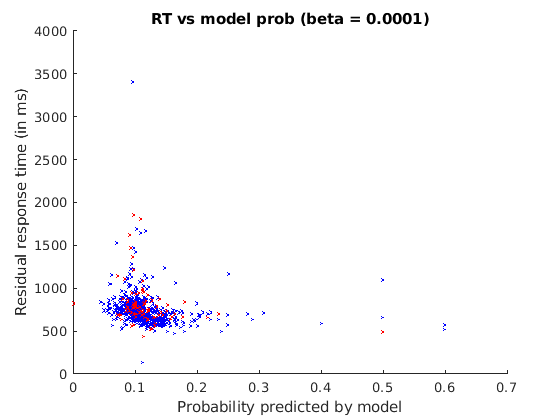

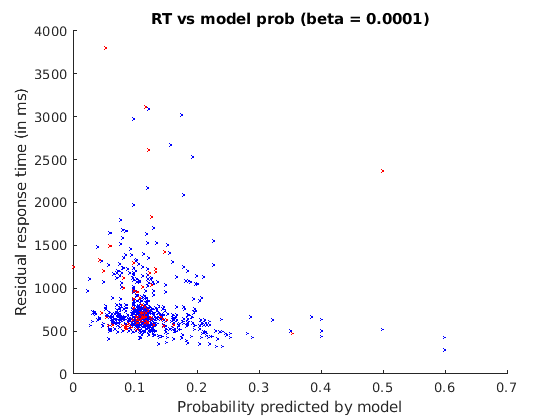

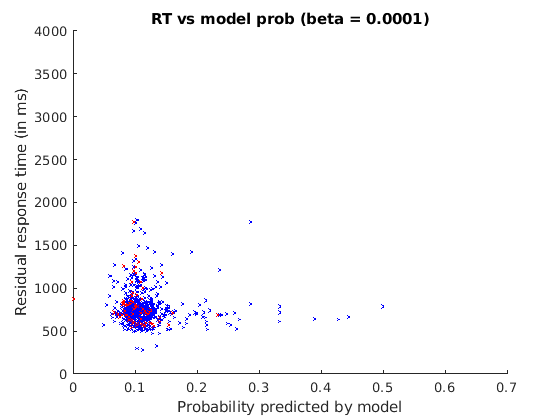

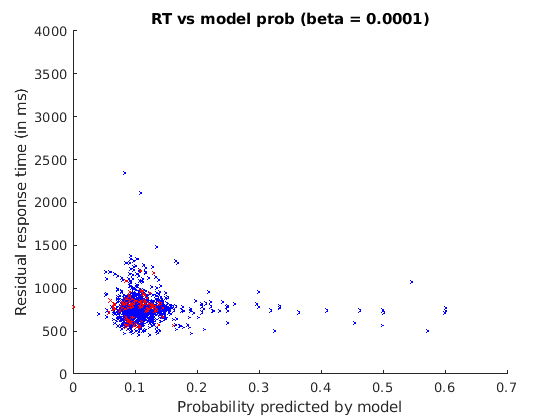

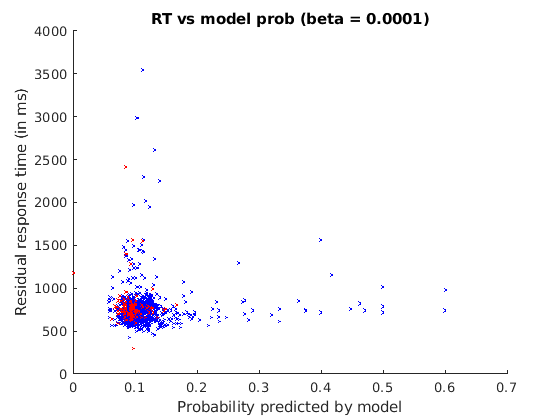

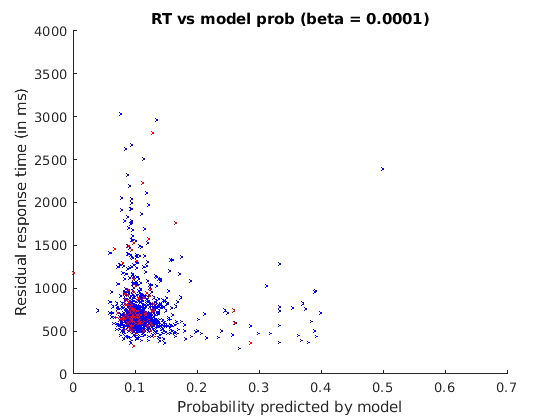

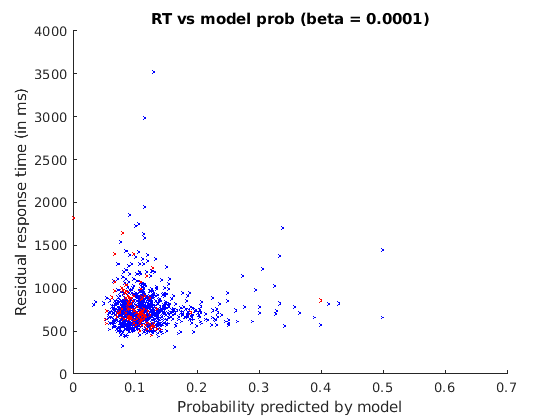

% in this file: 
% Fit the mixed effects model to the reaction times without preprocessing. 
% Use the target sequence to compute the probabilities. 
% Preprocess the residuals and fit a linear model for residuals vs probabilities. 
% Author: AKshay Krishnan

% Paths to data CSV files
% target - keys pressed through the sequence
target_file = readmatrix("railH/target-small-graph-h-02.csv");
% trial - the count at which the particular key was pressed
trial_file = readmatrix("railH/trial-small-graph-h-02.csv");
% rt - reaction time file
rt_file = readmatrix("railH/rt-small-graph-h-02.csv");
% graph - adjacency list
graph_file = readmatrix("railH/graph-small-graph-h-02.csv");
% folder to store the plots
plots_folder = 'railH/plotscatter/';

% initializing variables that are used to store the data read from these
% files
RT = [];
trial = [];
target = [];
ID = []; 
log_trial = [];
cluster = [];
mat_size = size(rt_file); % number of subjects
mkdir(plots_folder);

for i = 1:mat_size(1)
    % each row of the file is data for one subject.
    % rmmissing removes the NaNs at the end that occur becuase of varying
    % lengths of the sequence for each subject. 
    this_RT = transpose(rmmissing(rt_file(i, :)));
    
    RT = [RT; this_RT];
    trial = [trial; transpose(1:length(this_RT))];
    log_trial = [log_trial; log(transpose(1:length(this_RT)))];
    target = [target; transpose(rmmissing(target_file(i, :)))];
    cluster = [cluster; transpose(rmmissing(cluster_file(i, :)))];
    ID = [ID; i*ones(size(this_RT))];
end

% creating a table
pretest_table = table(ID, trial, log_trial, target, RT, cluster);
pretest_table.target = categorical(pretest_table.target);
pretest_table.ID = categorical(pretest_table.ID);

% fitting the LME model
model = fitlme(pretest_table, 'RT ~ log_trial + target + (log_trial | ID)');
% residuals of the model + intercept (to avoid negative values of the
% residuals). 
residual_intercept = model.Coefficients.Estimate(1) + residuals(model);
residual_rt = residuals(model);

% plot the residuals if necessary
% scatter(pretest_table.trial(pretest_table.ID == categorical(1)), pretest_table.RT(pretest_table.ID == categorical(1)), '.')
% scatter(pretest_table.trial(pretest_table.ID == categorical(1)), residual_intercept(pretest_table.ID == categorical(1)), '.')

% range of beta values at which are to be evaluated
beta_values = logspace(-4, 1, 20);

% list of subjects are to be analysed
subject = 1:mat_size(1);
results = [];

for subj = subject
    % sequence of keys and reaction residuals for this subject
    x = pretest_table.target(pretest_table.ID == categorical(subj));
    r = residual_intercept(pretest_table.ID == categorical(subj));
    
    errors = [];   % list of RMSE for different beta 
    beta_count = 1;  % counter for iterations - used to save images
    mkdir(plots_folder+string(subj)) % folder for each subject
    
    % for each beta value
    for b = beta_values
        % first determine the model's belief by iterating over the sequence
        belief = zeros([15, length(x)]);
        % the belief of x at each timestep is the sum of prob of all
        % previous time steps where x occured. An alternative way of
        % implementing this is to move from i = 1:t and update the value of
        % x(i) at t. 
        for t = 1:length(x)
            for i = 1:t
                belief(x(i), t) = belief(x(i), t) + prob(t - i, b);
            end
        end
        % a is the transition probability for each transition in the
        % sequence
        a = zeros([length(x), 1]);
        % n in the transition probability matrix at a particular instant
        n = zeros([15, 15]);
        
        % computing the transition probabilities based on the new counting
        % rule
        for t = 1:length(x)-1
            for i = 1:15
                n(i, x(t+1)) = n(i, x(t+1)) + belief(i, t);
            end
            a(t+1) = n(x(t), x(t+1))/sum(n(x(t), :));
        end

        rt_filtered = [];
        a_filtered = [];
        
        rt_mean = mean(r);
        rt_std = std(r);
        % post-processing reaction times
        for i = 150:length(x)
            if r(i) > 100 && r(i) < 3000 && abs(r(i) - rt_mean) < 3*rt_std
                rt_filtered = [rt_filtered; r(i)];
                a_filtered = [a_filtered; a(i)];
            end
        end
        linear_model = fitlm(a_filtered, rt_filtered);
        figure;
        plot(linear_model);
        xlabel('Probability predicted by model');
        ylabel('Residual response time (in ms)');
        title('RT vs model prob (beta = '+string(b)+', RMSE = '+string(linear_model.RMSE)+')')
        linear_model.RMSE
        saveas(gcf, plots_folder+string(subj)+'/rt-vs-a-'+string(beta_count)+'.png');
        beta_count = beta_count + 1;
        errors = [errors, linear_model.RMSE];
        %}
    end

    figure;
    plot(beta_values, errors);
    xlabel('beta values');
    ylabel('RMSE (in ms)');
    title('RMSE vs beta for' + string(subj));
    saveas(gcf, plots_folder+string(subj)+'/rmse-b.png');
    figure;
    semilogx(beta_values, errors);
    xlabel('beta values');
    ylabel('RMSE (in ms)');
    saveas(gcf, plots_folder+string(subj)+'/rmse-logb.png');

    close all;
end

function [p] = prob(t, beta)
    p = exp(-beta*t)*(1 - exp(-beta));
end
